# Raw signal dimensionality

We searched for two basis sets for the fluorescent data from the lip and tongue.  Exploring the data, we found that the two data sets, measured with an excitation light of 415 nm, are approximately 2 (lip) or 3 (tongue) dimensional.  They could be a little higher. 

We tested the idea that the** lip basis set is a subset of the tongue**, which is known to contain both porphyrin and chlorophyll that is not present on the lip.  Specifically, we asked if the tongue basis set could predict each of the basis functions in the lip.  

**Analysis from 500-600nm**

- We can get an excellent match using 3 basis functions for **tongue **

- We asked whether using a linear model of the tongue, we can fit the lip data as well.  We find that from 500-600nm, **a 3 dimensional model of the tongue fits the lip data pretty well, 4 is very well.**

- We can fit the **lip well with 3 bases**, but not 2.

- We asked whether using a linear model of the lip, we can fit the tongue data.  We find that  **4 or more Lip bases fit the tongue data**.  This is a bit odd since the lip data themselves only need 3.

**Analysis from 500-700nm**

- From 500-700nm 3 basis functions fit the tongue data separately; but they do not cross-fit (i.e., tongue basis predicts lip)

- Four dimensions fits the data separately well; the cross-fit (i.e., tongue basis predicts lip) is still not great.

We think that fitting from the tongue from 500-700 emphasizes the role of the porphyrins and chlorophyll, which are not important for the lip.  So we have to add more and more dimensions until we get to fit the lip.  But if we restrict to 500-600, the fluorophores are similar and we can fit back and forth.

**Note about tissue optics**

We explored whether we could make the two come together if we assume that there is a transmission function through the tissue that differs between tongue and lip.  That will take us on an expedition of fitting using a diagonal matrix (wave x wave) to relate the two sets of basis functions.  We will find a low dimensional parameterization of the diagonal matrix.

When done, we will test to see which fluorophores have emission functions, including perhaps some transmittance through blood with different amounts of oxygenation, that fall within the basis for the tongue and/or lip.

## Initialize the database and ISET

ieInit;

% Wavelength samples
waves = 500:700;

% Read in the database
[T,dataDir] = oeDatabaseCreate;

normalizationP = -1;   % Normalize for unit length, using oeReadFiles.

% This checks the quality of the fit of the data.
dimensionality = [2 3 4 5];

% SVD criterion for explained variance, if less than 1.
% criterion = 0.999;
% 
% % If criterion is more than 1, then we treat it as the number of
% % dimensions.
% criterion = 3;
% 
% % The difference (delta) in dimensions between the tongue, which is always
% % equal (deltaDim = 0) or less than the number of dimensions for the lip.
% deltaDim = 0;

## Read the tongue data

We tried various normalization approaches.  They are all the same.  

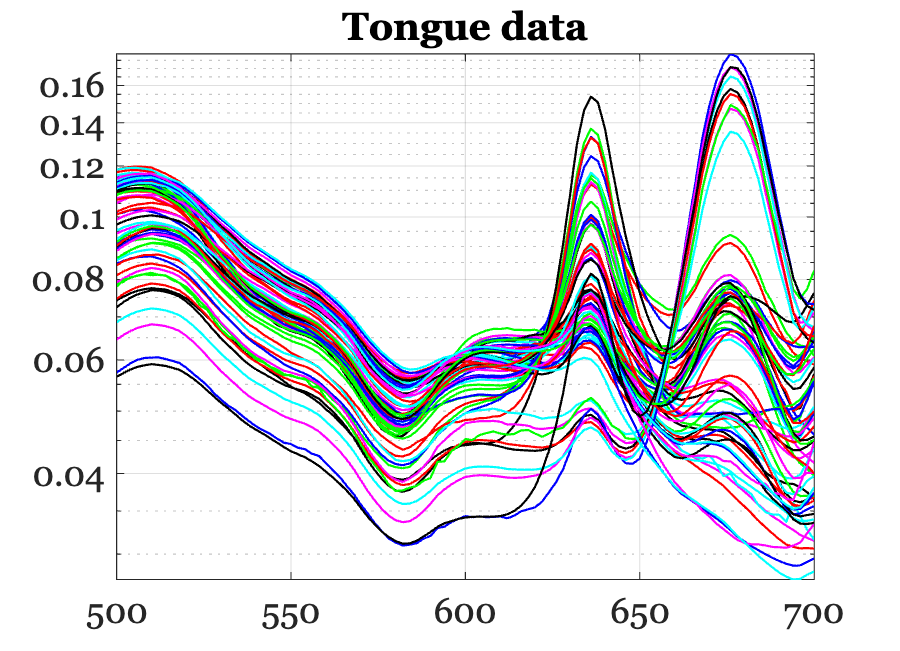

files405 = ieTableGet(T,...
    'ewave',405, ...
    'substrate','tongue');
files415 = ieTableGet(T,...
    'ewave',415, ...
    'substrate','tongue');
filesAll = cat(1,files405,files415);

dataTongue = oeReadFiles(filesAll,'waves',waves,'normalized wave',normalizationP);

ieFigure;
semilogy(waves,dataTongue);
grid on;
title('Tongue data');

## Set the dimensionality of the tongue data

Perform SVD explicitly, rather than using the pca() method.

[UT, ~, ~] = svd(dataTongue, 'econ');


## Plot the accuracy when using the linear model

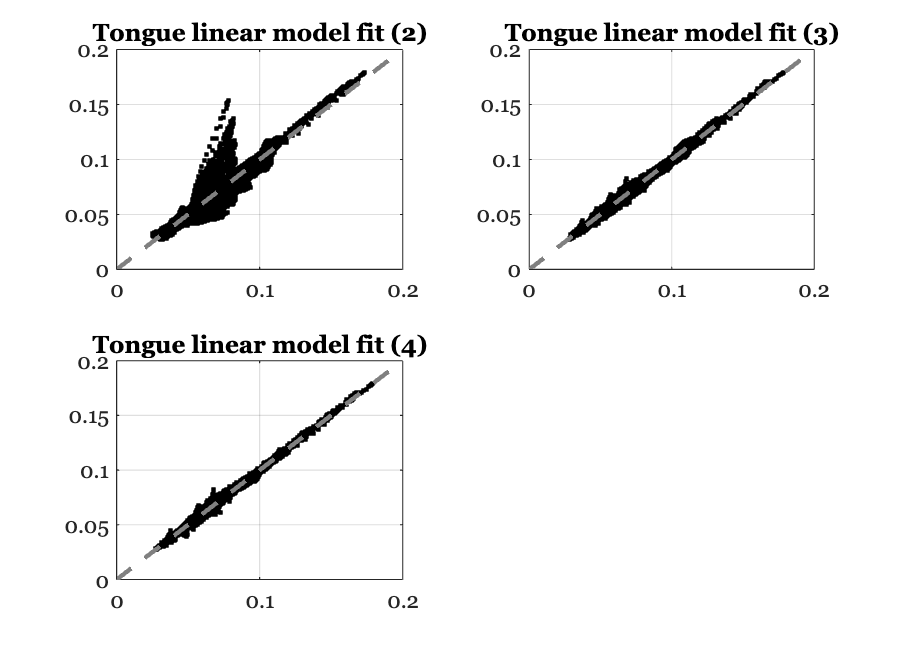

ieFigure;
tiledlayout(2,2);
for dd = dimensionality
    wgts = UT(:,1:dd)'*dataTongue;
    est = UT(:,1:dd)*wgts;
    nexttile;
    plot(est(:),dataTongue(:),'k.');
    identityLine;
    grid on;
    title(sprintf('Tongue linear model fit (%d)',dd));
end

## Read the Lip data

files405 = ieTableGet(T,...
    'ewave',405, ...
    'substrate','lip');
files415 = ieTableGet(T,...
    'ewave',415, ...
    'substrate','lip');
filesAll = cat(1,files405,files415);
dataLip = oeReadFiles(filesAll,'waves',waves,'normalized wave',normalizationP);


## Fit the lip data from the reduced tongue data

Without first calculating any bases, we can predict the lip data from the tongue data.  No basis approximation.

If they live in the same space, then it shouldn't be a problem.  They both have noise.  Not sure how that helps or hurts.

We find the matrix, M, such that we can multiply the tongue data and predict the lip data.


$${L_d =\;T}_d M$$


The special case would then be to replace the tongue data with a linear model approximation (say finding the basis functions) and use that subspace to make the prediction.  We do that below.

Here we try different dimensions of the tongue and see how well they fit the lip.

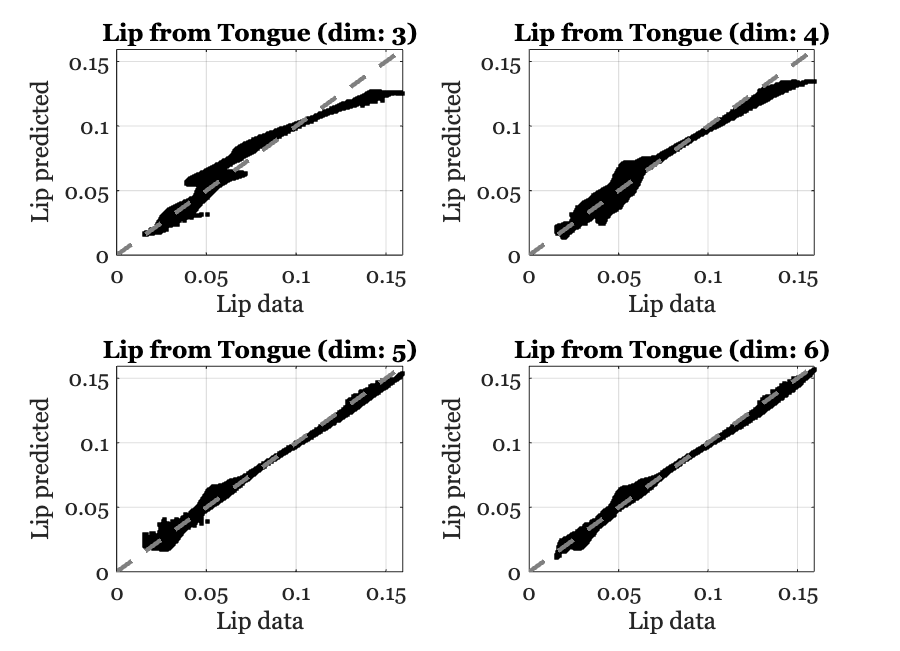

ieFigure;
tiledlayout(2,2)
for ii=3:6
    B = UT(:,1:ii);
    wgts = B'*dataTongue;
    dataTongueReduced = B*wgts;
    M = pinv(dataTongueReduced)*dataLip;
    dataLipP = dataTongueReduced*M;

    nexttile;
    plot(dataLip(:),dataLipP(:),'k.');
    xlabel('Lip data'); ylabel('Lip predicted'); grid on;
    title(sprintf('Lip from Tongue (dim: %d)',ii));
    identityLine;
end

## Find the lip bases

[UL, S, ~] = svd(dataLip, 'econ');
% if criterion < 1
%     eigenvalues = diag(S).^2;
%     totalVariance = sum(eigenvalues);
%     explainedVarianceRatio = eigenvalues / totalVariance;
% 
%     % Thresholding
%     cumulativeVariance = cumsum(explainedVarianceRatio);
%     dimensionality = find(cumulativeVariance >= criterion, 1, 'first');
% else
%     % One less than tongue.  My choice.
%     dimensionality = criterion;
%     dimensionality = dimensionality - deltaDim;
% end


## Fit the lip data with several dimensions

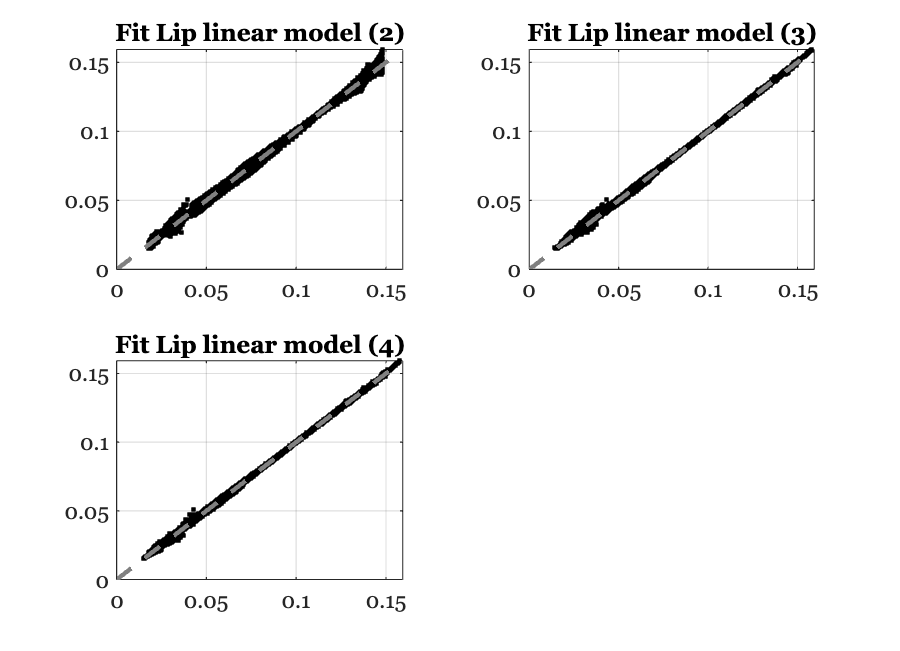

ieFigure;
tiledlayout(2,2)
for dd = dimensionality
    wgts = UL(:,1:dd)'*dataLip;
    est = UL(:,1:dd)*wgts;
    nexttile;
    plot(est(:),dataLip(:),'k.');
    identityLine;
    grid on;
    title(sprintf('Fit Lip linear model (%d)',dd));
end

## Fit the tongue with the lip bases

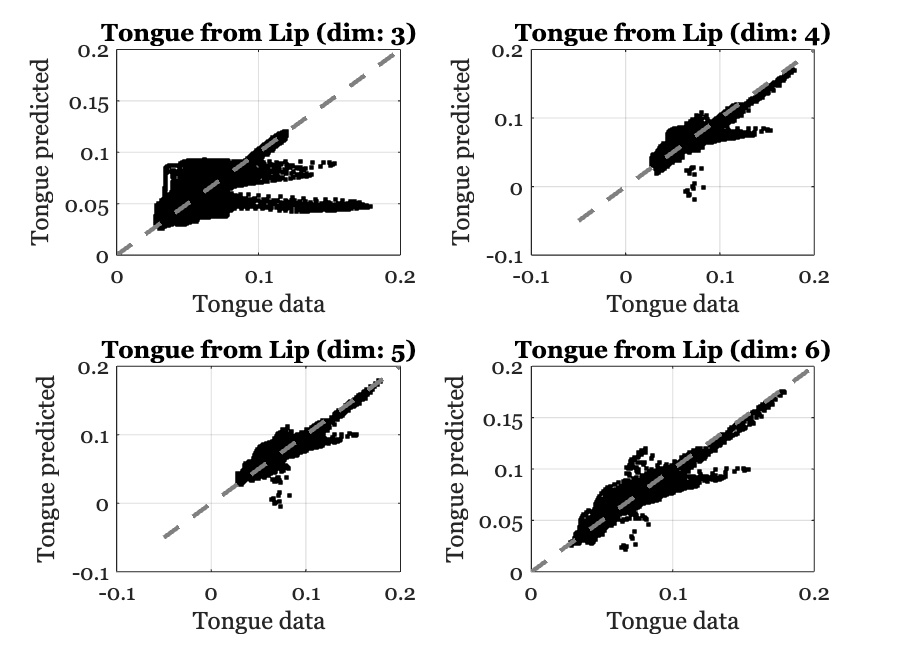

ieFigure;
tiledlayout(2,2)
for ii=3:6
    B = UL(:,1:ii);
    wgts = B'*dataLip;
    dataLipReduced = B*wgts;
    M = pinv(dataLipReduced)*dataTongue;
    dataTongueP = dataLipReduced*M;

    nexttile;
    plot(dataTongue(:),dataTongueP(:),'k.');
    xlabel('Tongue data'); ylabel('Tongue predicted'); grid on;
    title(sprintf('Tongue from Lip (dim: %d)',ii));
    identityLine;
end

## Compute bases with svd

% UL = UL(:,1:dimensionality);
% ieFigure;
% plot(waves,UL,'k-');
% grid on;
% xaxisLine;
% title('Lip');
% 
% ieFigure;
% wgts = UL'*dataLip;
% est = UL*wgts;
% plot(dataLip(:),est(:),'k.');
% identityLine;
% grid on; xlabel('Measured'); ylabel('Estimate');
% title('Lip');
% 
% ieFigure;
% plot(waves,dataLip,'k-'); hold on;
% plot(waves,est,'b:');
% title(sprintf('Lip linear model: %d',size(UL,2)));

## Can we fit the Lip bases using the Tongue bases?

If we think that the tongue has the same fluorophores as the lip, except it also has porphyrin and chlorophyll, then we should be able to predict the lip data as weighted sums of the tongue data.  Or, equivalently, we should be able to predict the lip bases as weighted sums of the tongue bases.


$$U_L =U_T \;w$$


% wgts = UT'*UL;
% ULpred = UT*wgts;
% sym1 = {'r-','g-','b-','k-','m-','c-'};
% sym2 = {'r--','g--','b--','k--','m--','c--'};
% 
% ieFigure;
% rowcol = ceil(sqrt(size(ULpred,2)));
% tiledlayout(rowcol,rowcol);
% % 
% for ii=1:size(UL,2)
%     nexttile;
%     hA = plot(waves,ULpred(:,ii),sym1{ii}); hold on;
%     hB = plot(waves,UL(:,ii),sym2{ii}); hold on;
% end
% 
% title('Cross fit lip from Tongue')
% legend([hA,hB],{'Predicted UL from UT','UL'});
% % xaxisLine;
% grid on;

## Is the problem tissue optics?

Suppose that there is a different wavelength filter in the tongue, $D_T$,  and lip, $D_L$.  Then we might have a pair of diagonal matrices that differ for the bases from the lip and tongue fluorophore signals.  We can combine the two diagonal matrices into one


$$D_{L\;} U_L =D_T U_T$$



$$U_L =D\;U_T$$


So a next project is to find a low-dimensional representation of the combined diagonal matrix, $D_\phi$, and search for its parameters, $\phi$ and the weights, $\omega$ that would satisfy


$$U_{L\;} =D_{\phi } U_T \omega$$


Here is a link to Gemini's solution in Matlab:  [https://g.co/gemini/share/1f70dfeefdde](https://g.co/gemini/share/1f70dfeefdde)

There is search code, written by ChatGPT, that we can check.  It takes oeSolveLipTongueCGPT() and returns the matrix and a diagonal.

% % Do the fit
% poly_degree = 6;
% [wgts, D_diag] = oeSolveLipTongueCGPT(UL, UT, poly_degree);
% disp(wgts)
% 
% % Show the Diagonal transmittance term.
% ieFigure; 
% plot(waves,D_diag,'k-');
% xlabel('Wavelength (nm)'); ylabel('Transmittance');

% % Compare the predicted and actual lip basis functions
% sym1 = {'r-','g-','b-','k-','m-','c-'};
% sym2 = {'r--','g--','b--','k--','m--','c--'};
% ULpred = diag(D_diag)*UT*wgts;
% 
% ieFigure;
% tiledlayout(rowcol,rowcol);
% % 
% for ii=1:size(UL,2)
%     nexttile;    
%     hA = plot(waves,ULpred(:,ii),sym1{ii}); hold on;
%     hB = plot(waves,UL(:,ii),sym2{ii}); hold on;
% end
% 
% legend([hA,hB],{'Predicted UL from UT','UL'});
% % xaxisLine;
% grid on;

## Now predict the data

% UTDiag = diag(D_diag)*UT;
% wgts = pinv(UTDiag)*dataLip;
% dataLipP = UTDiag*wgts;
% 
% ieFigure;
% plot(dataLip(:),dataLipP(:),'k.');
% grid on; xlabel('Lip Data'); ylabel('Lip Predicted');
% identityLine;